# Varying population size; gap timing

## load and preprocess data

fds = fileDatastore('N-*.mat', 'ReadFcn', @importdata);
Filenames = fds.Files;
npop = length(Filenames);

pop = zeros(1,npop);
C = cell(1,npop);
for i = 1:npop
    load(Filenames{i});
    C{1,i} = c;
    nums = regexp(Filenames{i},'\d*','Match');
    nums = str2double(nums);
    pop(i) = nums(end);
end

[pop, order] = sort(pop);
[r,d] = size(pop);
index = bsxfun( @plus, order, (0:r-1)'*d );
C = C';
C = C(index')';

## analyze data

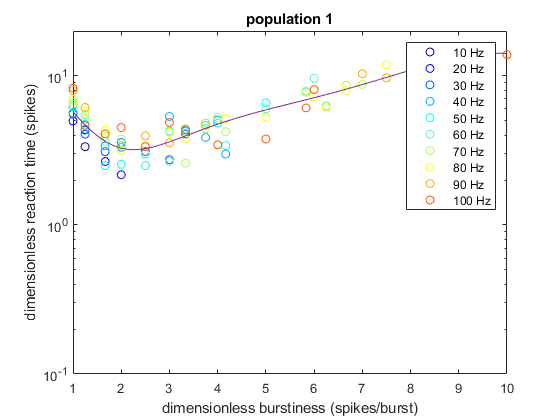

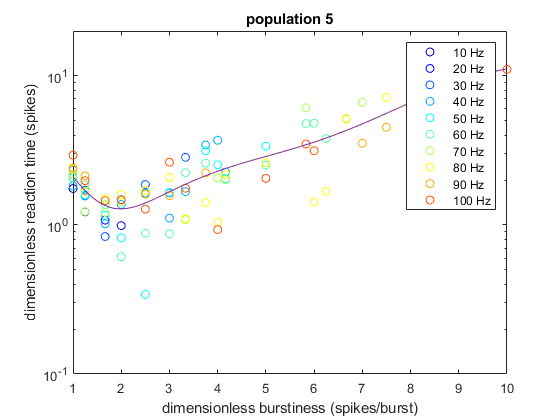

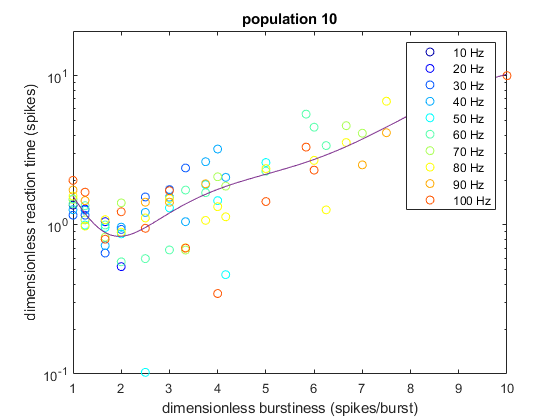

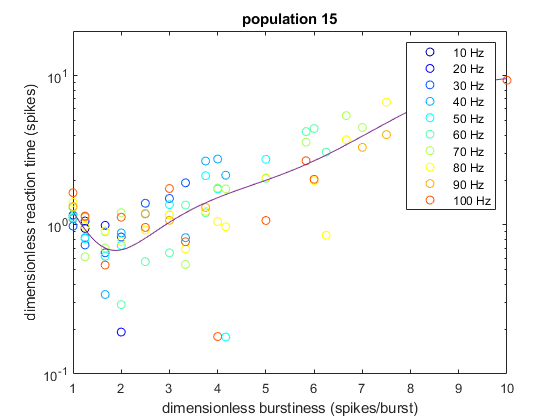

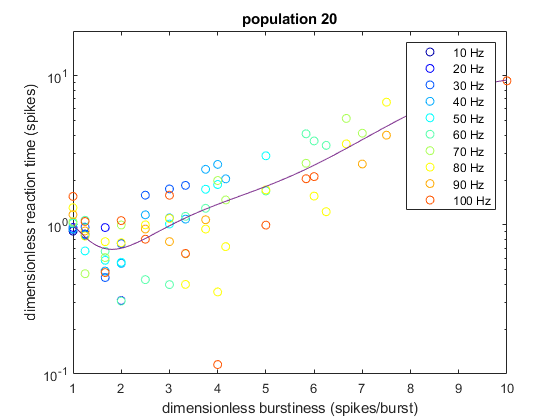

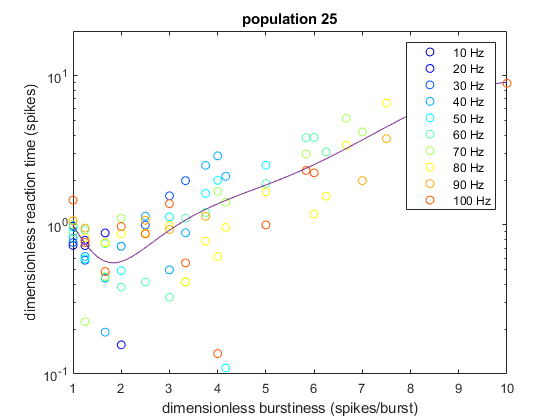

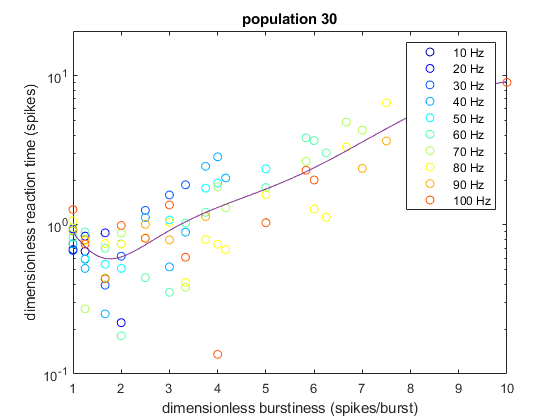

% generate a random color for each firing rate
mycolors = jet(10);
fr_vals = 10:10:100;

P = zeros(npop,6); % preallocate matrix to hold polynomial coeff for each population
for k = 1:npop
    figure;
    c = C{k};
    nparams = size(c,1); % number of sets of firing rate parameters
    ntrials = size(c,2)-5; % number of trials

    RT = zeros(nparams, ntrials);
    for i = 1:nparams
        for j = 1:ntrials
            RT(i,j) = c{i,j}.performance(1,3);
        end
    end

    params = c(:,ntrials+1:ntrials+5);
    params = cell2mat(params);
    lambda2 = params(:,2);
    k2 = params(:,4);
    fr_exact = params(:,5);
    fr = round(fr_exact,-1);
    fr2 = lambda2./k2;
    RT = median(RT,2);
    
    % let x and y denote the relevant dimensionless variables
    y = RT.*fr_exact./1000;
    x = fr2;

    % average together y values with the same firing rate and x value
    x1 = [];
    y1 = [];
    for i = 1:length(fr_vals)
        rows2 = find(fr == fr_vals(i));
        this_x = x(rows2);
        this_y = y(rows2);
        x_vals = unique(this_x);
        y_vals = zeros(length(x_vals),1);
        for j = 1:length(x_vals)
            y_vals(j) = median(this_y(this_x == x_vals(j)));
        end
        semilogy(x_vals, y_vals, 'o', 'Color', mycolors(i,:))
        x1 = [x1; x_vals];
        y1 = [y1; y_vals];
    hold on
    end
    % now average together all y values with the same x value
    x2 = unique(x1);
    y2 = zeros(length(x2),1);
    for j = 1:length(x2)
        y2(j) = median(y1(x1 == x2(j)));
    end
    TF = ~isnan(y2);
    y2 = y2(TF);
    x2 = x2(TF);
    xx = 1:0.01:max(x2);
    p = polyfit(x2,y2,5);
    yy = polyval(p,xx);
    semilogy(xx,yy)
    hold off
    ylabel('dimensionless reaction time (spikes)')
    xlabel('dimensionless burstiness (spikes/burst)')
    title(['population ', num2str(pop(k))])
    ylim([0.1 20])
    legend('10 Hz','20 Hz','30 Hz','40 Hz','50 Hz','60 Hz','70 Hz','80 Hz','90 Hz','100 Hz')
    P(k,:) = p;
end

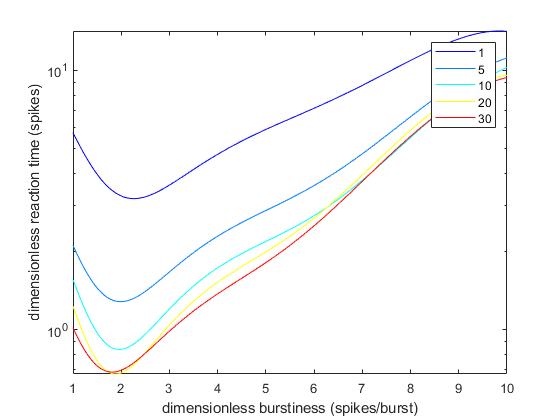

% choose 5 population sizes (for the sake of readability) and plot the
% corresponding polynomial fits
mycolors2 = jet(npop);
mypop = [1 2 3 5 7];
for k = 1:length(mypop)
    xx = 1:0.01:10;
    p = P(k,:);
    yy = polyval(p,xx);
    semilogy(xx,yy,'color',mycolors2(mypop(k),:))
    hold on
    ylabel('dimensionless reaction time (spikes)')
    xlabel('dimensionless burstiness (spikes/burst)')
end
hold off
legend('1','5','10','20','30')

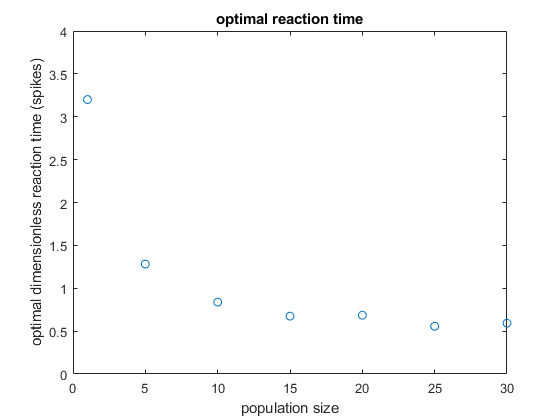

close all hidden;
optimal_burst_prediction = zeros(npop,1);
optimal_rt_prediction = zeros(npop,1);

for k = 1:npop
    xx = 1:0.01:10;
    p = P(k,:);
    yy = polyval(p,xx);
    [~,min_ind] = min(yy);    
    optimal_burst_prediction(k) = xx(min_ind);
    optimal_rt_prediction(k) = yy(min_ind);
end

plot(pop,optimal_rt_prediction, 'o')
ylim([0 4])
ylabel('optimal dimensionless reaction time (spikes)')
xlabel('population size')
title('optimal reaction time')

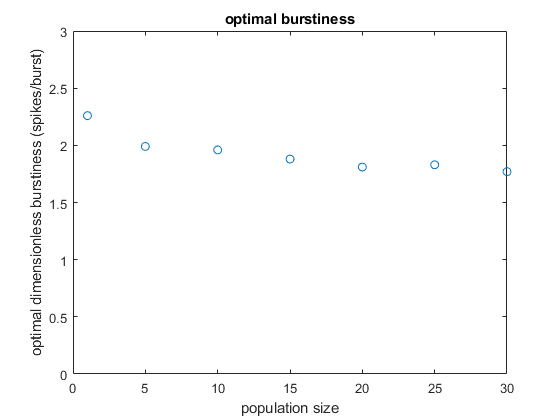


plot(pop,optimal_burst_prediction, 'o')
ylim([0 3])
ylabel('optimal dimensionless burstiness (spikes/burst)')
xlabel('population size')
title('optimal burstiness')